# Datascience of Physiological Time Series: Homework-1 

# Author: Veda Narayana Koraganji

#### Question 1: Describe the signal in a couple of sentences. What do you see? What do the values represent?

    To answer this question, first I plotted the ECG from the given .csv file as shown in Figure 1. It is evident the signal has a distinct periodicity, to look at this closely Figure 2 has been plotted for the first 10 seconds. It's a classical ECG data (Although, pretty obvious from the homework statement), and high quality on top that, given its 1000 Hz sampling rate.

     Upon close inpection of Figure 1, there are two locations(labeled as Loc. 1 and Loc.2 in Figure 1) in time that the signals gets distorted, one of the reason might be movement of the subject at this time. 

    The values in the data represents the data collected from the Electrodes and the periodic highs represent 

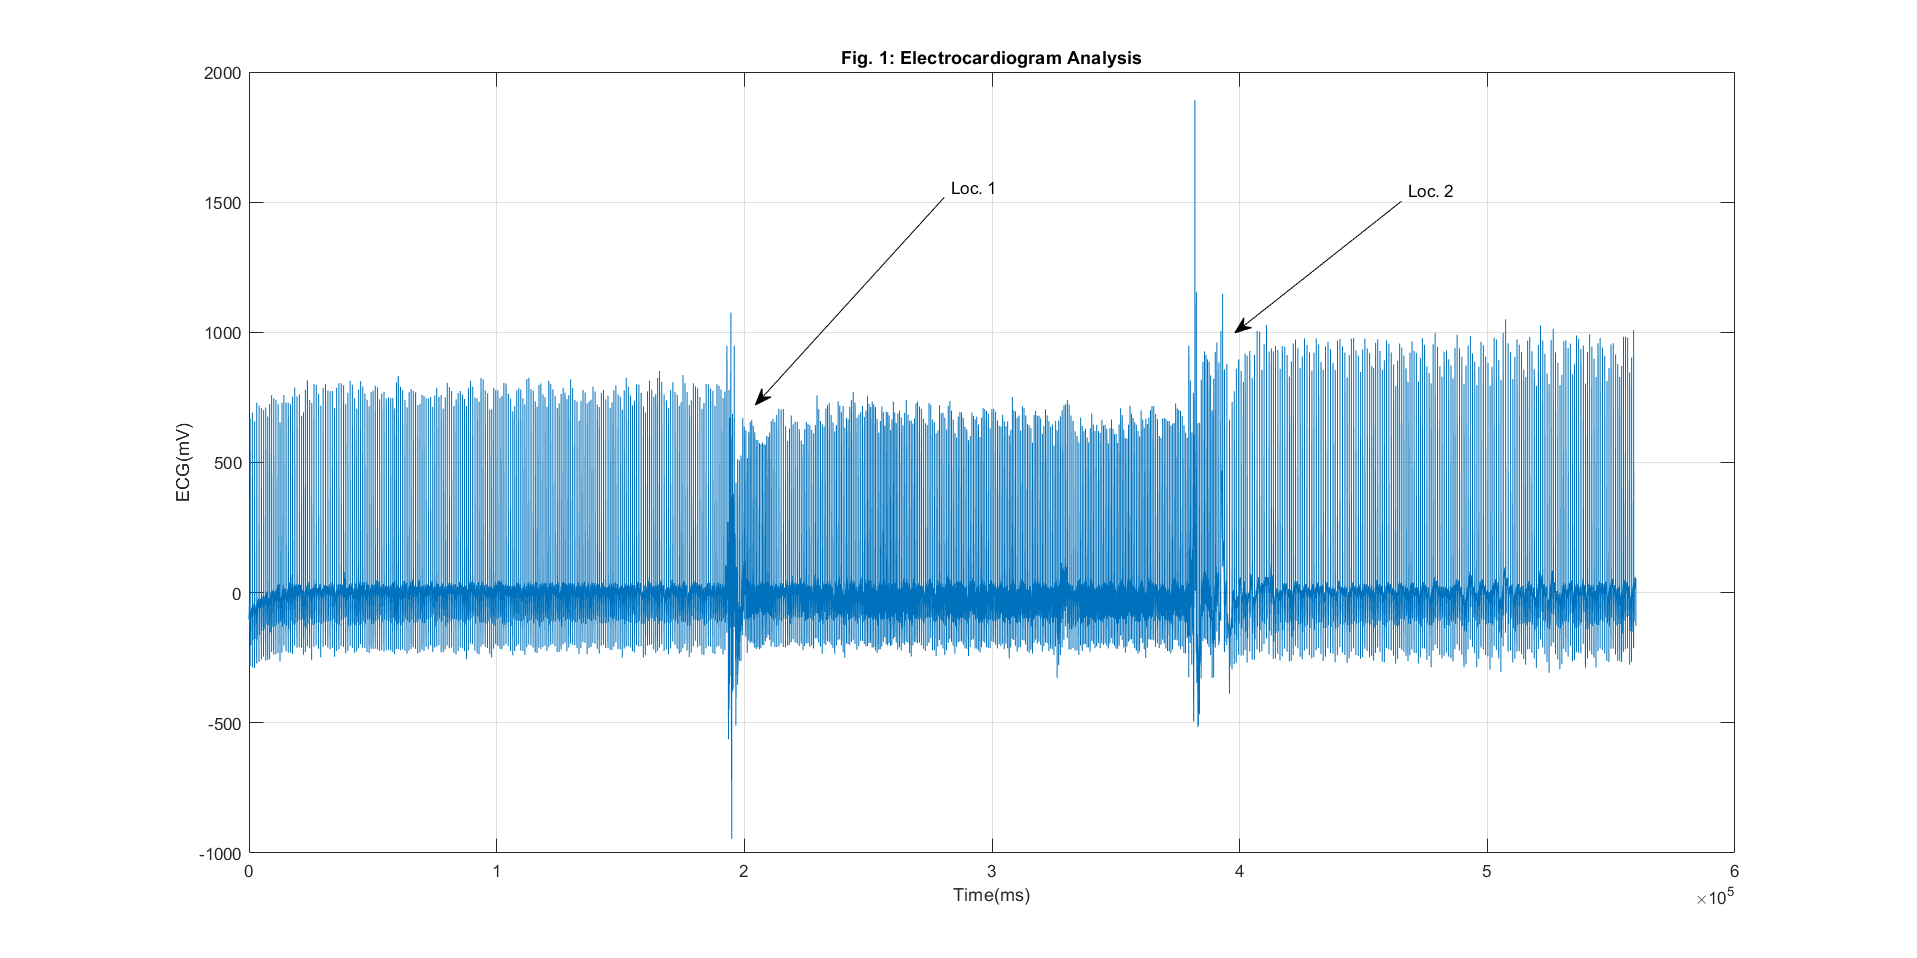

clear
% Load data from the CSV file using the readFile function, into a table
file = 'ECG_hw1.csv';
fileData = readFile(file);

% Extract the data from table into arrays for easy manipulation
ecgData = table2array(fileData(:,1));
timeMs = (1:length(ecgData))';

% plot the data and set annotations for the locations
plot(timeMs, ecgData);
xlabel('Time(ms)');
ylabel('ECG(mV)');
title('Fig. 1: Electrocardiogram Analysis')
grid on
annotation('textarrow',[0.4925 0.394],[0.7938 0.5772],'String','Loc. 1')
annotation('textarrow',[0.7311 0.6441],[0.79 0.6524],'String','Loc. 2')

% For live scripts only: resize the figure to increase the width, this
% change will be applies to all figures unless explicitly changed again
set(gcf,'Position',[0,0,2000,1000])

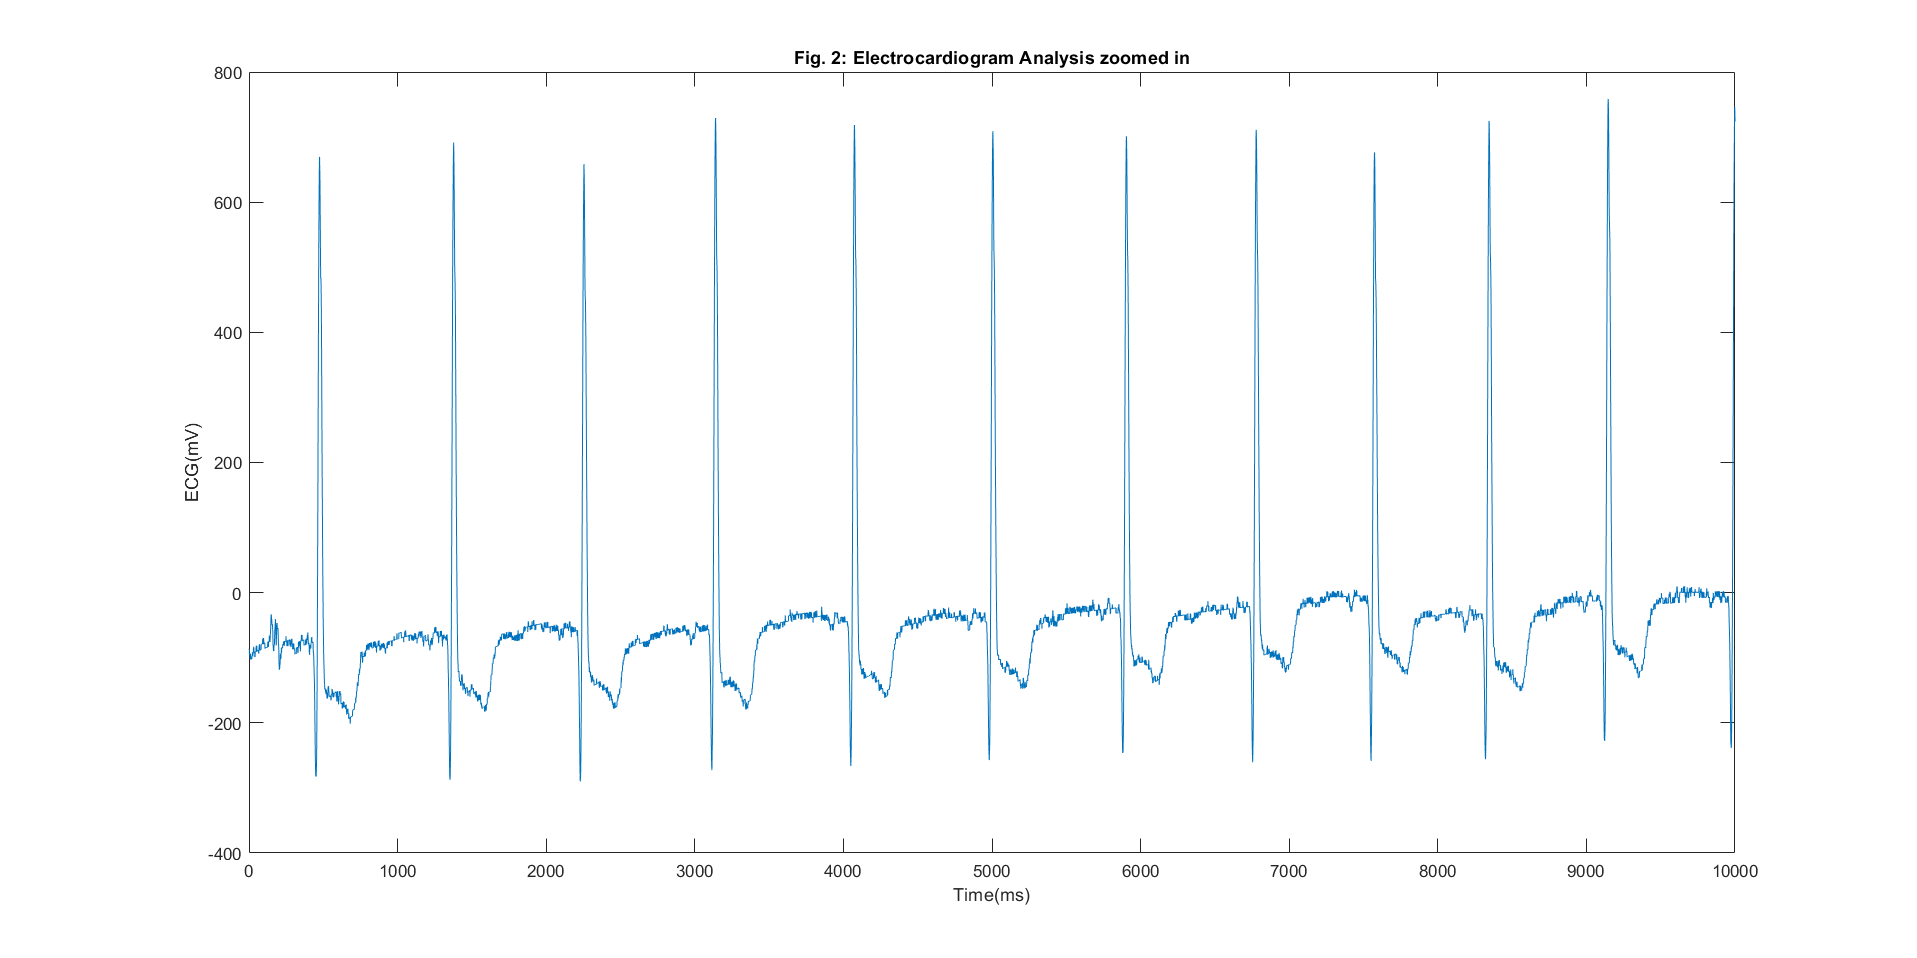


% plot the first 10 seconds of the signal
plot(timeMs(1:10000),ecgData(1:10000))
xlabel('Time(ms)');
ylabel('ECG(mV)');
title('Fig. 2: Electrocardiogram Analysis zoomed in')

grid on;

#### Question 2: Create a simple code for detecting each beat of the feart in your signal.

The following code detects the peaks in the signal and stores the output in a file with the specified format. 

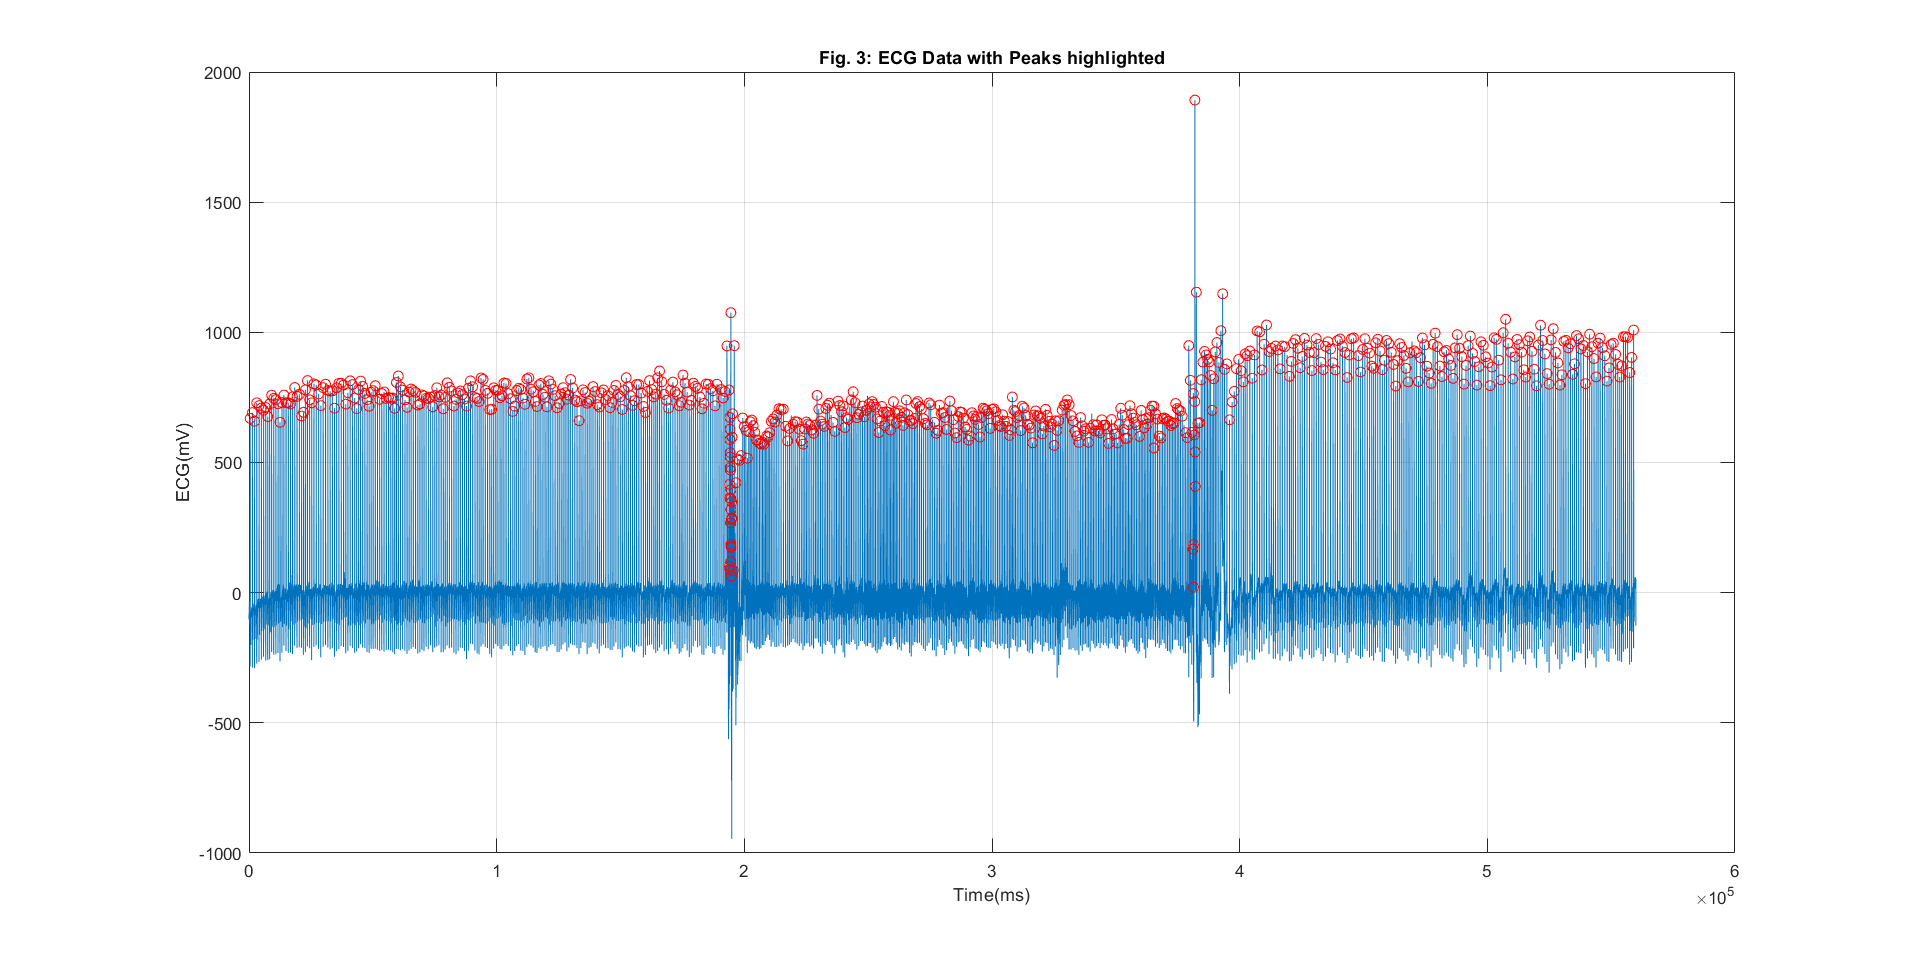

% As per the instructions in the assignment
% Simple code for implementing without using inbuilt funtions

%initialize the variables to store outputs
heartBeats = {};
peak = [];
trough = [];
peak(1) = 0;
trough(1) = 0;

%minProminence will set the sensitivity of the peak detection
minProminence = 300;

for i = 2:length(ecgData)-1
    % detect a peak using the below code
    if ((ecgData(i - 1) < ecgData(i)) && (ecgData(i) > ecgData(i + 1))) && (ecgData(i) > 0)
        peak = [peak; ecgData(i)];
        
        % check the prominence of the peak with the last known trough
        if (peak(end) - trough(end)) > minProminence
            heartBeats = [heartBeats; {ecgData(i),i}];   
        end
        
        % detect the trough, needed for confirming prominence
    elseif ((ecgData(i - 1) > ecgData(i)) && (ecgData(i) < ecgData(i + 1)))
        trough = [trough; ecgData(i)];
    end
end

% converting the cell to matrix
heartBeats = cell2mat(heartBeats);

% To make my future self life easier i'll be using functions in the signal processing toolbox
% [heartBeats, locaions] = findpeaks(ecgData,"MinPeakProminence",300);
% heartBeats = [heartBeats, locations];

% Write the heart beat data to a file in the 
writetable(array2table([heartBeats(:,2)/1000, heartBeats(:,1)],"VariableNames",...
    {'Time of beat occurence(seconds)','Signal value at beat(mV)'}),'Heartbeat_data',"FileType",...
    'text',"Delimiter",'tab');

plot(timeMs, ecgData, timeMs(heartBeats(:,2)), heartBeats(:,1), 'or');
xlabel('Time(ms)');
ylabel('ECG(mV)');
title('Fig. 3: ECG Data with Peaks highlighted')
grid on